# Classification of Heart Murmurs using audio feature extraction

The script demonstrates the complete AI based workflow to classify "Normal" and "Abnormal" heart sounds. The heart sounds are recorded in a .wav (audio) format and sampled at 2000Hz.  

For this application, we use the dataset provided by the [PhysioNet challenge of 2016](https://archive.physionet.org/pn3/challenge/2016/), consisting of over 3000 recordings of normal and abnormal hearts. These recordings were obtained at four different locations - aortic, pulmonic, trcuspid and mitral areas - using phonocardiograms.

The training and validation set are provdied. The training set contains 3240 audio samples of both "Normal" and "Abnormal" heart murmurs. The "Normal" heart mumrmers are labeled as -1 and "Abnormal" ones are labeled as 1. The validation set contains 301 samples and no labeling is provided for this validation dataset. 

## Data Exploration in Time Domain

% plot one sample of normal and abnormal heart murmur
tiledlayout(1,2)
fig = gcf;
fig.Position(3:4) = [1300,500]; 
% Analyze and Plot normal PCG
nexttile
[audio_normal,fs] = audioread("training\training-a\a0007.wav");
analyzeNormal = analyzeTimeDomain(T.Data{7,1},2000)

analyzeNormal = struct with fields:
       peakAmplitude: 0.4680
        rmsAmplitude: 2.5127e-05
             rmsDBFS: -85.4023
    zeroCrossingRate: 0.0338
              status: 0



plot(audio_normal(1:8000,1)); xlabel("Samples"); title("Normal PCG for heart Murmurs");

% Analyze and plot abnormal PCG
[audio_abnormal,fs] = audioread("training\training-a\a0001.wav");
analyzeAbnormal = analyzeTimeDomain(audio_abnormal,fs)

analyzeAbnormal = struct with fields:
       peakAmplitude: 0.2100
        rmsAmplitude: 2.4461e-05
             rmsDBFS: -78.6733
    zeroCrossingRate: 0.0546
              status: 0


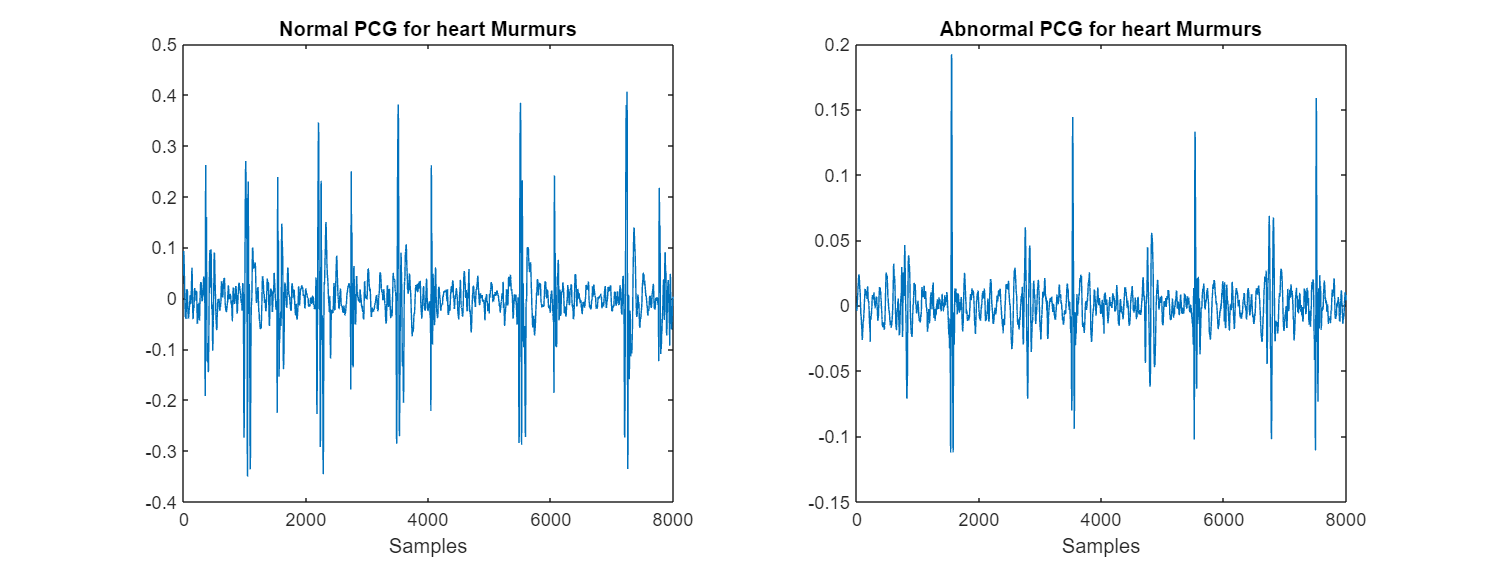

nexttile
plot(audio_abnormal(1:8000,1)); xlabel("Samples"); title("Abnormal PCG for heart Murmurs");

## Data Exploration in Frequency Domain

The power spectrum of normal and abnormal PCG signals has been generated. In the power spectrum for normal PCG signals, the first two consecutive spikes near the Y axis shows the presence of S1 (beginning of systole) and S2 (end of systole) sounds of heart. The variations in the duration and intersities are considered as abnormalities in the PCG signal, which is reflected by the power sepctrum of abnormal PCG.  The plot for abnormal PCG also reflects a lot of high frequencies present in the signal which are considered as abnormal activity of the heart. The power spectrum can also be analyzed using signalAnalyzer app. 

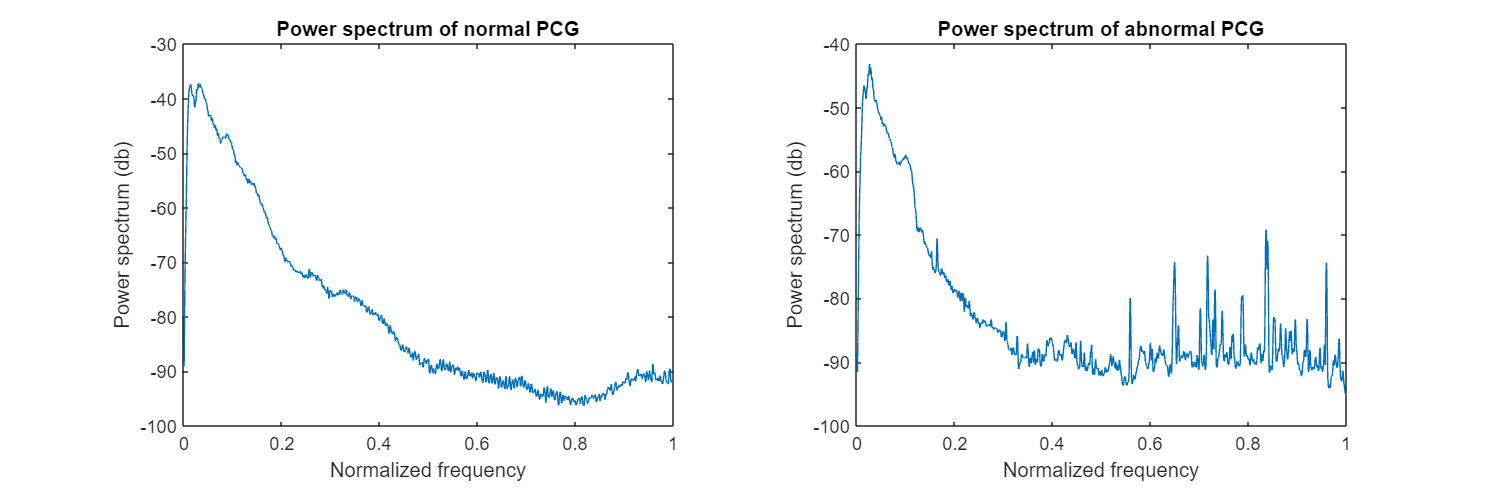

[p_n,f_n] = pspectrum(audio_normal);
[p_a,f_a] = pspectrum(audio_abnormal);
figure;

tiledlayout(1,2)
fig = gcf;
fig.Position(3:4) = [1200,400]; 
nexttile;
plot(f_n/pi,pow2db(p_n)); 
title('Power spectrum of normal PCG')
xlabel('Normalized frequency'); ylabel('Power spectrum (db)');
nexttile;
plot(f_a/pi,pow2db(p_a));
title('Power spectrum of abnormal PCG'); 
xlabel('Normalized frequency'); ylabel('Power spectrum (db)');

% signalAnalyzer(audio_normal, audio_abnormal)

## Data Access as Datastores

The audioDatastore provides a convinient way to access large amount of data stored in various folders. The folders contains meta data files with extension .dat and .hea files. For this workflow we need only audio files, and hence will access only .wav files from all the subfolders. We will create two audioDatastores, one for training data and one for validation data. 

cp = currentProject;
train_folderPath = fullfile(cp.RootFolder, 'training');

%folder = 'C:\Users\garimas\MATLAB\Projects\Garima_Audio_Classification\training';  % Replace with the actual folder path
adsTrain = audioDatastore(train_folderPath, 'FileExtensions', '.wav', 'IncludeSubfolders', true);

Val_folderPath = fullfile(cp.RootFolder,'validation');
adsVal = audioDatastore(Val_folderPath,"FileExtensions",'.wav','IncludeSubfolders',true);

Fs = 2000; % sampling rate

## Feature Engineering

A separate function named featuresExtraction has been created that leverages the audioFeatureExtractor function of MATLAB to streamline the feature extraction for audio signals. We have extracted MFCC and Spectral skewness from the audioDatastores. More features such as MFCC delta, MFCC delta delta, LPC, GTCC and more can also be extracted by same audioFeatureExtarctor, and can be added to the selected features in future work. Features for training and test data is extarcted by using the respective datastores. 

reset(adsTrain)
% Create an audioFeatureExtractor object for MFCC extraction
aFE = audioFeatureExtractor(SampleRate=Fs, Window=hamming(1024,"periodic"),...
    OverlapLength=512, ...
    spectralCentroid=true,spectralEntropy=true, ...
    spectralSkewness=true,shortTimeEnergy=true );

% Initialize variables to store the extracted features
numFiles = numel(adsTrain.Files);
FeaturesTrain = cell(numFiles, 1);

% Extract MFCC features for each audio file
for i = 1:numFiles
    audio = read(adsTrain);
    features = extract(aFE, audio);
    FeaturesTrain{i} = normalize(features,'range');
end

% Normalize the MFCC features
%normalizedFeatures = normalize(cat(1, mfccFeatures{:}), 'range'); % normalized between range [0 1]

reset(adsVal);
% Initialize variables to store the extracted features
numFiles = numel(adsVal.Files);
FeaturesTest = cell(numFiles, 1);

% Extract MFCC features for each audio file
for i = 1:numFiles
    audio = read(adsVal);
    audio_table = array2table(audio);
    features = extract(aFE, audio);
    FeaturesTest{i} = normalize(features,'range');
end

% Normalize the MFCC features
%normalizedTestFeatures = normalize(cat(1, mfccFeatures{:}), 'range'); % normalized between range [0 1]

## Access Labels for the Dataset

The labels of the training set is saved in the reference.csv file in each training folder. In this section we extarcted and combine all the training labals together, to make it suitable for machine learning training. 

% from the training folder and subfolders access the reference.csv file
% that contains label information
data_dir = fullfile(pwd, 'training');
folder_list = dir([data_dir filesep 'training*']);
reference_table = table();
for ifolder = 1:length(folder_list)
    disp(['Processing files from folder: ' folder_list(ifolder).name])
    current_folder = [data_dir filesep folder_list(ifolder).name];
    
    % Import ground truth labels (1, -1) from reference. 1 = Normal, -1 = Abnormal
    reference_table = [reference_table; importReferencefile([current_folder filesep 'REFERENCE.csv'])];
end

Processing files from folder: training-a
Processing files from folder: training-b
Processing files from folder: training-c
Processing files from folder: training-d
Processing files from folder: training-e
Processing files from folder: training-f



% get labels for train dataset and match its size equal to training
% features to make it suitable for classification (by classification
% learner app or writing codes) 

label_train = [];
for i = 1:size(FeaturesTrain,1)
j = size(FeaturesTrain{i,1},1);
value_label = table2array(reference_table(i,'record_label'));
label = value_label * ones(j,1);
label_train = [label_train;label];
end

## Data Prep for Machine learning

Create a table with featuresTrain and labels. The featuresTrain is a set of normalized features including MFCC and Spectral skewness. The first 13 columns shows the MFCCs and 14th column represents the spectral skewness. Preview the first and last 8 rows of features and associated labels.  

data = cell2mat(FeaturesTrain);
T1 = table(data,label_train);
head(T1)

                        data                        label_train
    ____________________________________________    ___________

     0.12598     0.33986     0.51306    0.091757         1     
     0.18803     0.47286     0.45448     0.10631         1     
      0.5185     0.76107     0.10351     0.81679         1     
     0.19383      0.3518     0.32057     0.02012         1     
    0.069159     0.25161     0.78987     0.17056         1     
     0.17793     0.34121     0.52424    0.086838         1     
     0.45779     0.78094     0.17734     0.48813         1     
     0.40815      0.5468    0.091708           0         1     



tail(T1)

                         data                         label_train
    ______________________________________________    ___________

    0.19488      0.39126      0.44101      0.54308        -1     
     0.2392      0.31784      0.41377      0.56017        -1     
    0.41263      0.61281      0.24969            1        -1     
    0.32043      0.50633      0.23022      0.56988        -1     
    0.52118      0.67172     0.066961     0.021643        -1     
    0.98743       0.8151    0.0051901     0.068285        -1     
    0.55744      0.74252       0.1731     0.095598        -1     
    0.70841      0.82216     0.020749     0.027567        -1     



% classificationLearner

Mdl = fitcknn(data,label_train,'NumNeighbors',100,'Standardize',1)

Mdl =   ClassificationKNN
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [-1 1]
           ScoreTransform: 'none'
          NumObservations: 279554
                 Distance: 'euclidean'
             NumNeighbors: 100


  Properties, Methods


test_data = cell2mat(FeaturesTest(1,1));
pred = mypredict(Mdl,test_data);
%disp(['The accuracy rate for the classification model is ', num2str((1-error)*100),' %.'])

## Training of Machine Learning Model - optional

This section combines the training and optimization parts together in one line of code. In this section a binary deceion tree has been used for 2 class classification. The 'auto' is selected to optimize 'MinLeafSize' parameter. We can also select 'none' or 'all' for optimizing hyperparameters.  The optimization attempts to minimize the cross-validation loss (error) for `fitctree` by varying the parameters. By default Bayesian Optimizer is used by the fitctree function, but other methods such as 'gridsearch' and 'randomsearch' can also be utilized. 

% %options = struct("Optimizer","asha","UseParallel",true);
% Mdl = fitcecoc(data,label_train,"Holdout",0.3)
classerror = kfoldLoss(Mdl)

classerror = 0.2342

%MdlOpt = fitctree(data,label_train,'OptimizeHyperparameters','all');

Update the Model with the best hyperparameters to minimize the loss and maximize the accuracy. 

% MdlMod = fitctree(data,label_train,MinLeafSize=162,SplitCriterion="gdi",NumVariablesToSample=14,Holdout=0.3);
% ModClassError = kfoldLoss(MdlMod)
% disp(["Accuracy rate of the optimized model is",100-ModClassError*100,'%'])

Estimate predictor importance values by summing changes in the risk due to splits on every predictor and dividing the sum by the number of branch nodes. Compare the estimates using a bar graph.

% imp = predictorImportance(MdlOpt);
% figure;
% bar(imp);
% title('Predictor Importance Estimates');
% ylabel('Estimates');
% xlabel('Predictors');
% h = gca;
% h.XTickLabel = Mdl.PredictorNames;
% h.XTickLabelRotation = 45;
% h.TickLabelInterpreter = 'none';

Classify observations in cross-validated classification model by using kfoldPredict function. Create a confusion matrix that compares the true class values to the predicted class values.

% predicted_data = kfoldPredict(MdlMod);
% confusionchart(label_train,predicted_data)

To predict the labels of the test data, when true labels are not known, we can use the predict function to estimate the labels of the test data. 

% test_data = cell2mat(FeaturesTest);
% predicted_labels = predict(MdlOpt,test_data);